load("1DOF_WhiteNoiseForcingData.mat");
load("1DOF_SinusoidalForcingData.mat");

## Load Operation Ranges

load("minSpeedData.mat");
load("maxSpeedData.mat");
load("cruiseSpeedData.mat");

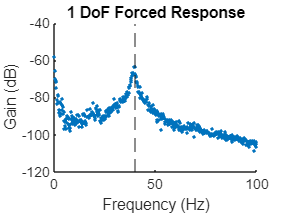

close all
hold on
plotRange = oneDOF_WNFD_freq_Hz_avg <= 100;
plot(oneDOF_WNFD_freq_Hz_avg(plotRange), oneDOF_WNFD_gain_dB_avg(plotRange),'.')
[~, peakIndex] = max(oneDOF_Gain);
xline(oneDOF_freqInput_Hz(peakIndex), '--', 'HandleVisibility','off'); % HandleVisibility omits this from the legend, crazy insane
% xline(minSpeed_freqInput_Hz, '--')
% xline(maxSpeed_freqInput_Hz, '--')
title("1 DoF Forced Response")
xlabel("Frequency (Hz)")
ylabel("Gain (dB)")
ylim([-120 -40])

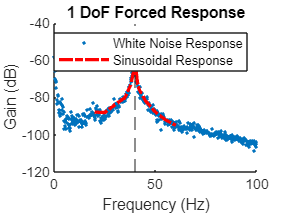

% Sensitivity
plot(oneDOF_freqInput_Hz, oneDOF_Gain, 'r-.', 'LineWidth', 2)
legend("White Noise Response", "Sinusoidal Response")